# **Procesamiento de Imagenes Digitales**

# **Taller 5**

## Cargar imagen

Cargue la imagen "bones.tif" y visualicela en la figure(1).

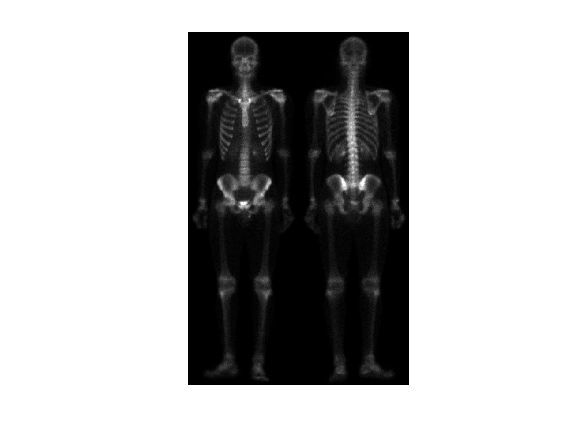

I=imread('bones.tif');
figure(1);
imshow(I);

## **Resalte los bordes de la imagen **

Detecte y enriquezca los bordes de la imagen,visualice en las figuras 2 y 3, usando las técnicas de: 

*Laplacian edge sharpening  *

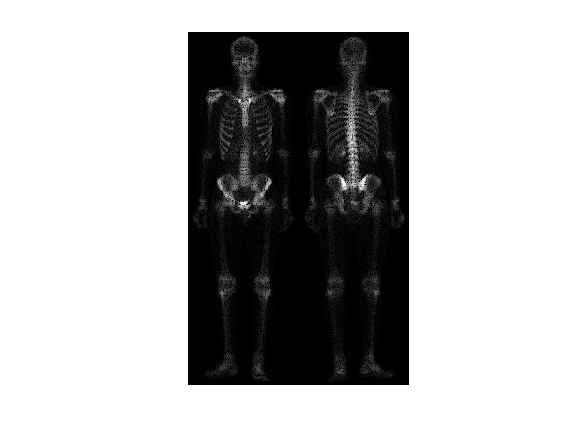

k1 = [1 1 1; 1 -8 1; 1 1 1];
Ifilter = imfilter(I,k1,'symmetric');
Iout = imsubtract(I,Ifilter);
figure(2);
imshow(Iout);

Se ve una pequeña mejoria pero se alcanza a apreciar puntos negros aun que inpiden la deferenciación completa de los bordes.

*The unsharp mask filter  *

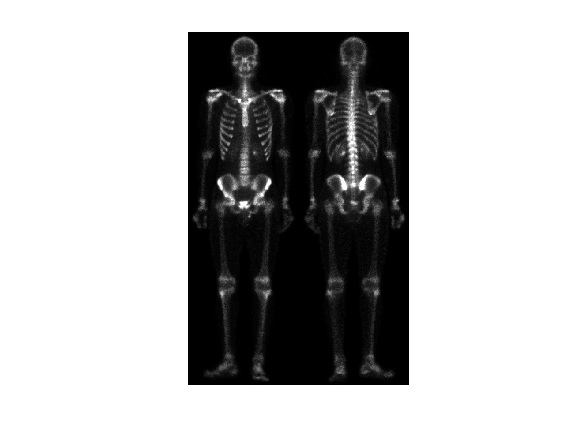

k2 = ones(31,31)/961;
Ismoothed = imfilter(I,k2,'symmetric');
Iedges = I - Ismoothed;
Ienhanced = I + Iedges;
figure(3);
imshow(Ienhanced);

Con el filtro de *The unsharp mask filter *la imagen se ve mejorada a medida que aumenta el tamaño de la ventana del filtro.